# Acción de una matriz sobre un vector

# Descomposición SVD (matriz 3x3)

### 1.- Vector inicial x (rojo)

x=[3;1;2]

x =      3
     1
     2


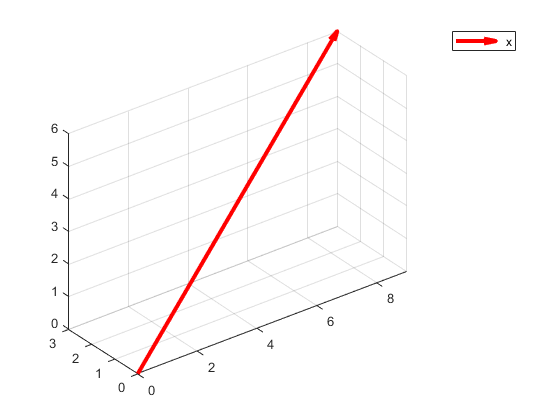

quiver3(0,0,0,x(1),x(2),x(3),3,'filled','r','LineWidth',3,'MaxHeadSize',0.1)
legend ('  x')
hold on
axis equal
grid on

### 2.- Vector transformado y= A.x (magenta)

A=[1,-2,1;2,-1,0;2,1,-1]

A =      1    -2     1
     2    -1     0
     2     1    -1


y=A*x

y =      3
     5
     5


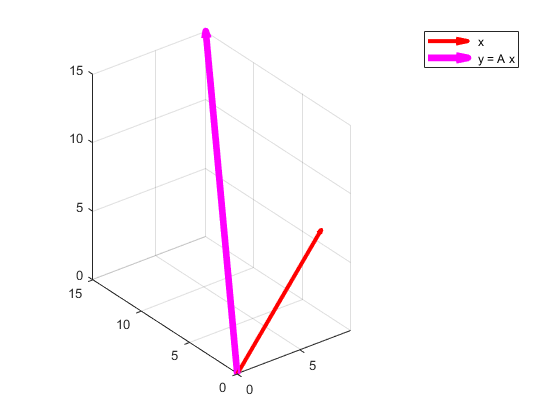

quiver3(0,0,0,y(1),y(2),y(3),3,'filled','m','LineWidth',5,'MaxHeadSize',0.1)
legend ('  x','  y = A x')

### 3.- Descomposición SVD de la matriz A:

[U S V]=svd(A)

U =    -0.6051    0.5780    0.5476
   -0.7033   -0.0657   -0.7078
   -0.3732   -0.8134    0.4462


S =     3.1675         0         0
         0    2.6368         0
         0         0    0.1197


V =    -0.8707   -0.4476    0.2037
    0.4863   -0.7220    0.4922
   -0.0732    0.5277    0.8463


vx=V'*x,svx=S*vx,usvx=U*svx

vx =    -2.2723
   -1.0093
    2.7960


svx =    -7.1976
   -2.6614
    0.3348


usvx =     3.0000
    5.0000
    5.0000


### 4.- Transformación de x por Vt:   Vt.x (verde)

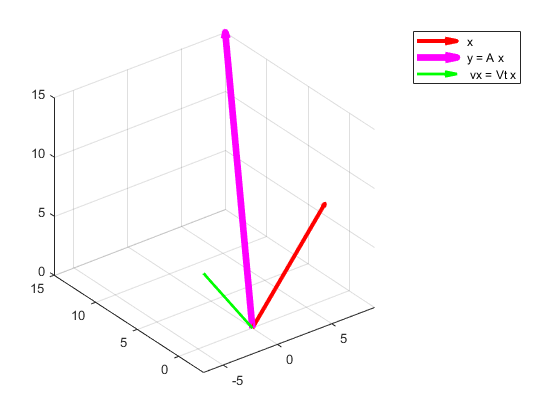

quiver3(0,0,0,vx(1),vx(2),vx(3),3,'filled','g','LineWidth',2,'MaxHeadSize',0.1)
legend ('  x','  y = A x','   vx = Vt x')

### 5.- Transformación de vx por S:   S.Vt.x (azul)

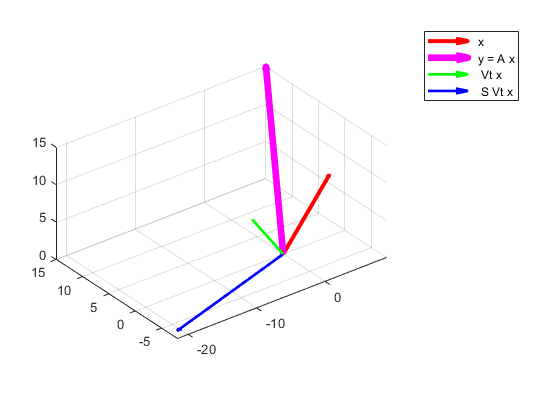

quiver3(0,0,0,svx(1),svx(2),svx(3),3,'filled','b','LineWidth',2,'MaxHeadSize',0.1)
legend ('  x','  y = A x','   Vt x','   S Vt x')

### 6.- Transformación final por U:   U.S.Vt.x (negro)

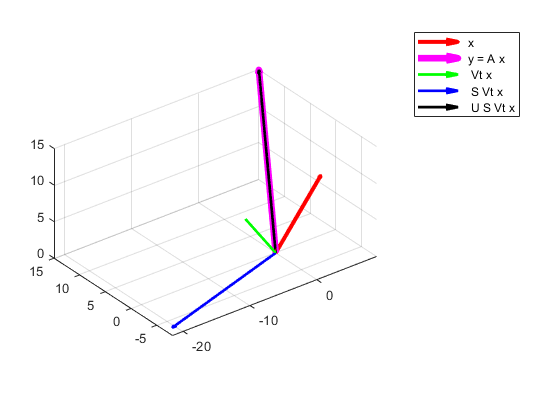

quiver3(0,0,0,usvx(1),usvx(2),usvx(3),3,'filled','k','LineWidth',2,'MaxHeadSize',0.1)
legend ('  x','  y = A x','   Vt x','   S Vt x','   U S Vt x')